# Trim and linearisation

## Flight conditions

% Flight conditions from the table
fc_a = struct();
fc_a.altitude = 40000;
fc_a.velocity = 300;

% Flight conditions for the Accelerometer Position Analysis
fc_apa = struct();
fc_apa.altitude = 15000;
fc_apa.velocity = 500;

## Create models

% High fidelity models
model_hi_a = find_f16_dynamics('LIN_F16Block_', 1, fc_a.altitude, fc_a.velocity, 5);
model_hi_apa = find_f16_dynamics('LIN_F16Block_', 1, fc_apa.altitude, fc_apa.velocity, 5);

% Low fidelity models
model_lo_a = find_f16_dynamics('LIN_F16Block_', 0, fc_a.altitude, fc_a.velocity, 5);
model_lo_apa = find_f16_dynamics('LIN_F16Block_', 0, fc_apa.altitude, fc_apa.velocity, 5);

## Cost function results

fprintf("model_hi_a.cost: %10e", model_hi_a.cost);

model_hi_a.cost: 5.057312e-02

fprintf("model_hi_apa.cost: %10e", model_hi_apa.cost);

model_hi_apa.cost: 7.185556e-06

fprintf("model_lo_a.cost: %10e", model_lo_a.cost);

model_lo_a.cost: 4.299705e-29

fprintf("model_lo_apa.cost: %10e", model_lo_apa.cost);

model_lo_apa.cost: 5.157226e-29

## Accelerometer Position Analysis

x_a = 0.0;
model_lo_apa_an = find_f16_dynamics('LIN_F16Block_with_an', ...
                                    0, fc_apa.altitude, fc_apa.velocity, 5);

% A and B matrices are the same
disp(isequal(model_lo_apa.ss.A, model_lo_apa_an.ss.A))

   1



disp(isequal(model_lo_apa.ss.B, model_lo_apa_an.ss.B))

   1




% C and D matrices contain a new row
disp(isequal(size(model_lo_apa.ss.C), [18, 18]))

   1



disp(isequal(size(model_lo_apa_an.ss.C), [19, 18]))

   1



disp(isequal(size(model_lo_apa.ss.D), [18, 4]))

   1



disp(isequal(size(model_lo_apa_an.ss.D), [19, 4]))

   1




% The top rows are still the same
disp(isequal(model_lo_apa.ss.C, model_lo_apa_an.ss.C(1:end-1, :)))

   1



disp(isequal(model_lo_apa.ss.D, model_lo_apa_an.ss.D(1:end-1, :)))

   1



% C and D for the normal accelerometer output.
fprintf("%e", model_lo_apa_an.ss.C(end, :))

0.000000e+000.000000e+00-3.243222e-050.000000e+00-9.679687e-060.000000e+003.987362e-039.929782e+000.000000e+000.000000e+009.664154e-010.000000e+000.000000e+002.084076e-020.000000e+000.000000e+000.000000e+000.000000e+00

fprintf("%f", model_lo_apa_an.ss.D(end, :))

0.0000000.0000000.0000000.000000

% Transfer function from the elevator (input 2) to 
% the normal accelerometer (output 19)
[tf_num, tf_den] = ss2tf(model_lo_apa_an.ss.A, model_lo_apa_an.ss.B, ...
                         model_lo_apa_an.ss.C, model_lo_apa_an.ss.D, 2);
tf_num = tf_num(19, :);
tf_elev_an = tf(tf_num, tf_den);
disp(fprintf("%e ", cell2mat(tf_elev_an.Numerator)))

0.000000e+00 4.209834e-01 2.290291e+01 4.045674e+02 1.727937e+03 -2.375761e+04 -3.176781e+05 -1.639526e+06 -5.127473e+06 -1.168019e+07 -1.574098e+07 -7.901189e+06 -5.914150e+04 7.463491e+02 4.870179e+00 -1.463774e-11 0.000000e+00 0.000000e+00 0.000000e+00    256



disp(fprintf("%e ", cell2mat(tf_elev_an.Denominator)))

1.000000e+00 8.050610e+01 2.580783e+03 4.234125e+04 3.875663e+05 2.115500e+06 7.644473e+06 2.058872e+07 3.951572e+07 5.029485e+07 4.056599e+07 1.553174e+07 5.630501e+05 1.073154e+05 1.158885e+03 -8.860380e-11 0.000000e+00 0.000000e+00 0.000000e+00    248



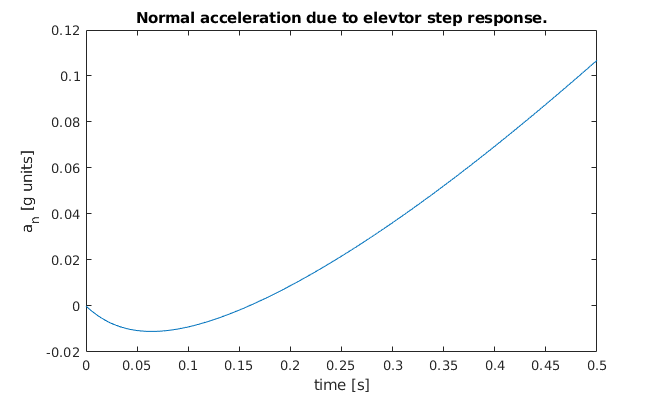

% Simulate the step responce of the transfer function
time_vector = 0:0.001:0.5;
u_elev = -ones(1, length(time_vector));

[y, t] = lsim(tf_elev_an, u_elev, time_vector);

plot(t, y)
xlabel('time [s]')
ylabel('a_n [g units]')
title('Normal acceleration due to elevtor step response.')

set(gcf,'units','points','position',[0,0, 500, 300])

% Display the transfer function zeros
zero(tf_elev_an)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
 -20.2000 + 0.0000i
 -20.2000 + 0.0000i
   9.7597 + 0.0000i
  -7.3529 + 0.0000i
  -7.2500 + 0.0000i
  -5.3925 + 0.0000i
  -0.3198 + 2.7408i


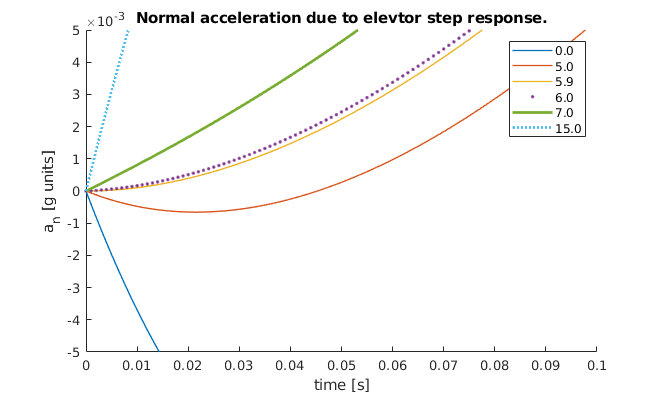

% Perform the same simulation for difference values of `x_a`.
clf
hold on

time_vector = 0:0.001:0.1;
u_elev = -ones(1, length(time_vector));

x_a_list = [0. 5. 5.9 6. 7. 15.];
style_list = ['-', '--', '.-', ':', '-', '--'];
width_list = [1, 1, 1, 1, 2, 2];

tf_list = [];
zero_list = [];
for i = 1:6    
    % Linearize model
    x_a = x_a_list(i) * 0.3048;
    model = find_f16_dynamics('LIN_F16Block_with_an', ...
                              0, fc_apa.altitude, fc_apa.velocity, 5);
    
    % Create transfer function
    [tf_num, tf_den] = ss2tf(model.ss.A, model.ss.B, ...
                             model.ss.C, model.ss.D, 2);
    tf_xa = tf(tf_num(19, :), tf_den);
    
    tf_list = [tf_list tf_xa];
    zero_list = [zero_list zero(tf_xa)];
    
    % Simulate step responce
    [y, t] = lsim(tf_xa, u_elev, time_vector);
    
    % Plot
    plot(t, y, style_list(i), ...
         'LineWidth', width_list(i), ...
         'DisplayName', sprintf("%3.1f", x_a_list(i)))
end
xlabel('time [s]')
ylabel('a_n [g units]')
title('Normal acceleration due to elevtor step response')
ylim([-0.005, 0.005])
legend()
set(gcf,'units','points','position',[0,0, 500, 300])
hold off

zero_list

zero_list = 	1.0e+04 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -6.7142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0020 + 0.0000i   0.0041 + 0.0000i  -0.0020 + 0.0000i  -0.0284 + 0.0000i  -0.0020 + 0.0000i  -0.0020 + 0.0000i
  -0.0020 + 0.0000i  -0.0020 + 0.0000i  -0.0020 + 0.0000i  -0.0020 + 0.0000i  -0.0020 + 0.0000i  -0.0020 - 0.0000i
   0.0010 + 0.0000i  -0.0020 - 0.0000i  -0.0011 + 0.0000i  -0.0020 - 0.0000i  -0.0014 + 0.0010i  -0.0007 + 0.0000i
  -0.0007 + 0.0000i  -0.0008 + 0.0000i  -0.0007 + 0.0000i  -0.0011 + 0.0000i  -0.0014 - 0.0010i  -0.0007 + 0.0000i
  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0007 + 0.0000i  -0.0002 + 0.0006i
  -0.0005 + 0.0000i  -0.0007 + 0.0000i  -0.0000 + 0.0003